# Linear effect of stimulus intensity (low < med < high)

Model (6cond)

parameter:

- 6 Stimulus onset

- `    cue ``H``igh x stim ``H``igh (onset03_stim)`

- `    cue ``H``igh x stim ``M``ed`

- `    cue ``H``igh x stim ``L``ow`

- `    cue ``L``ow x stim ``H``igh`

- `    cue ``L``ow x stim ``M``ed`

- `    cue ``L``ow x stim ``L``ow`

- `C``ue: onset01_cue`

- `E``xpect rating: onset02_ratingexpect, pmod_expectRT`

- `O``utcome rating: onset04_ratingoutcome, pmod_outcomeRT`

- Motion covariate: 24DOF + CSF

- Spike, as many spikes detected by fmriprep (FD spike threshold 0.9)

# Pain > (Vicarious & Cognitive) 

# Linear effect of stimulus intensity (low < med < high)

#### Pain > VC :: load dataset

clear all;
close all;

contrast_of_interest = 'P_VC_STIM_stimlin_high_gt_low'

contrast_of_interest = 'P_VC_STIM_stimlin_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_STIM_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32347188 bytes
Loading image number:    81
Elapsed time is 2.952090 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7687514  Bit rate: 22.87 bits


#### Pain > VC :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:08:18 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


#### Pain > VC :: Plot diagnostics, before l2norm

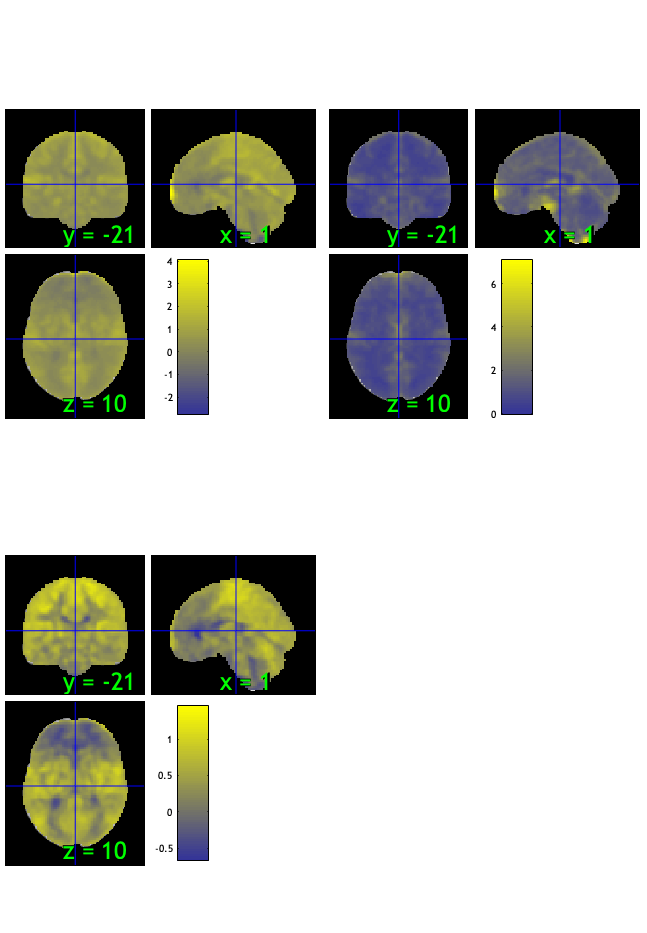

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 25.93%
Expected 4.05 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 51 55 62 
Uncorrected: 7 images		Cases 24 36 44 51 55 59 62 

Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 51.85%
Expected 4.05 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 2 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               <s

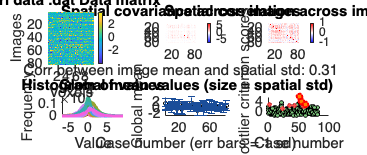

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:08:47 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain > VC :: run robfit

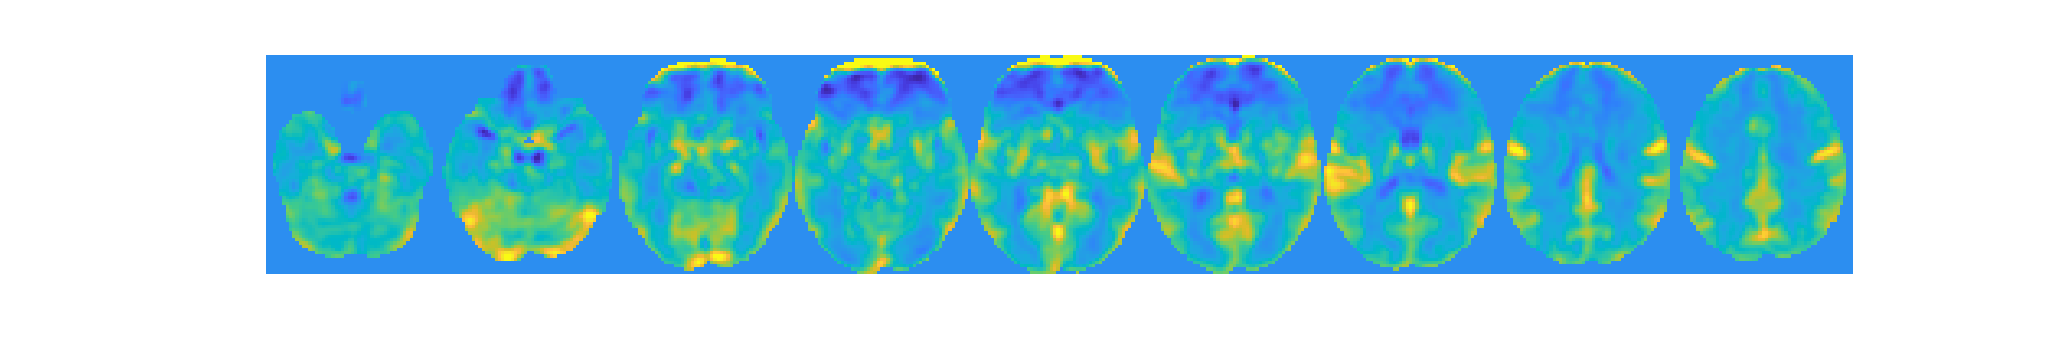

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Pain > VC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 81


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 3 participants, size is now 78


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0093"    "participants that are outliers:... sub-0098"    "participants that are outliers:... sub-0106"



disp(n);

    {'sub-0093'}    {'sub-0098'}    {'sub-0106'}



#### Pain > VC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain > VC :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


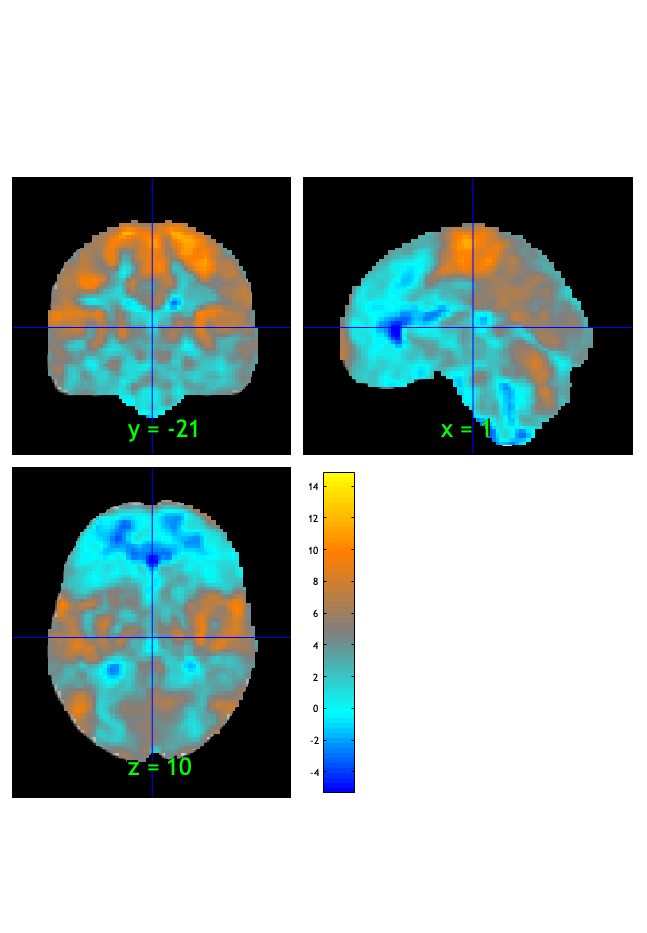

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:08:51 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.034838

Image   1
 35 contig. clusters, sizes   1 to 69254
Positive effect: 68418 voxels, min p-value: 0.00000000
Negative effect: 1154 voxels, min p-value: 0.00000167


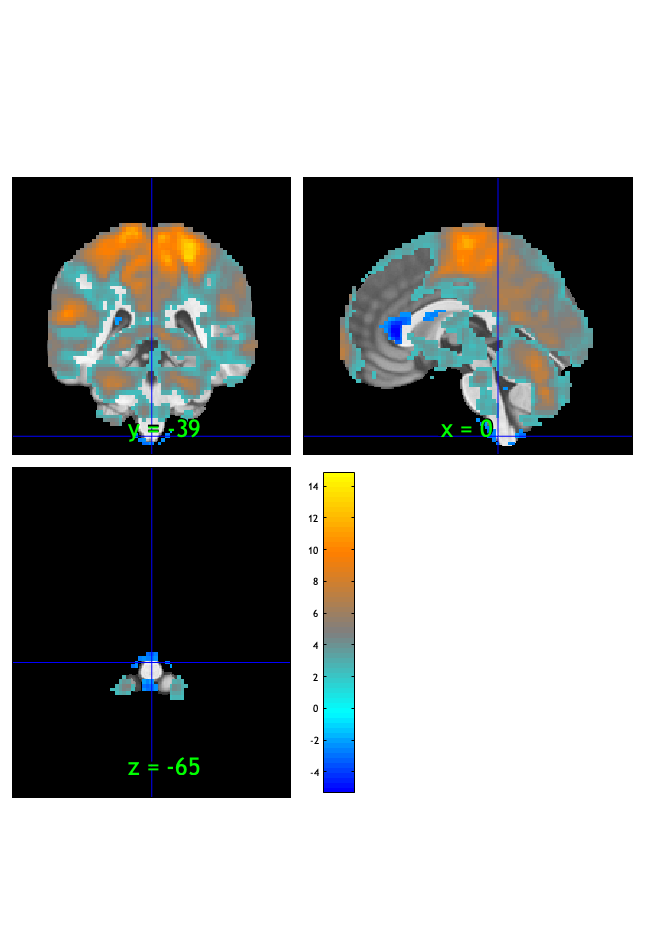

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:08:53 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000420

Image   1
 39 contig. clusters, sizes   1 to 41659
Positive effect: 41939 voxels, min p-value: 0.00000000
Negative effect:  39 voxels, min p-value: 0.00000167


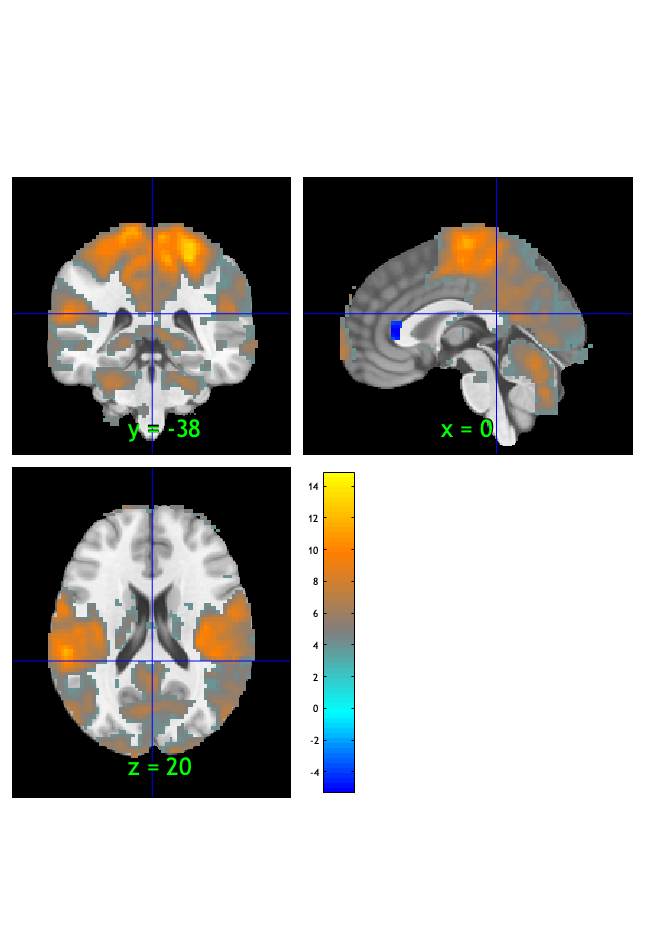

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:08:54 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


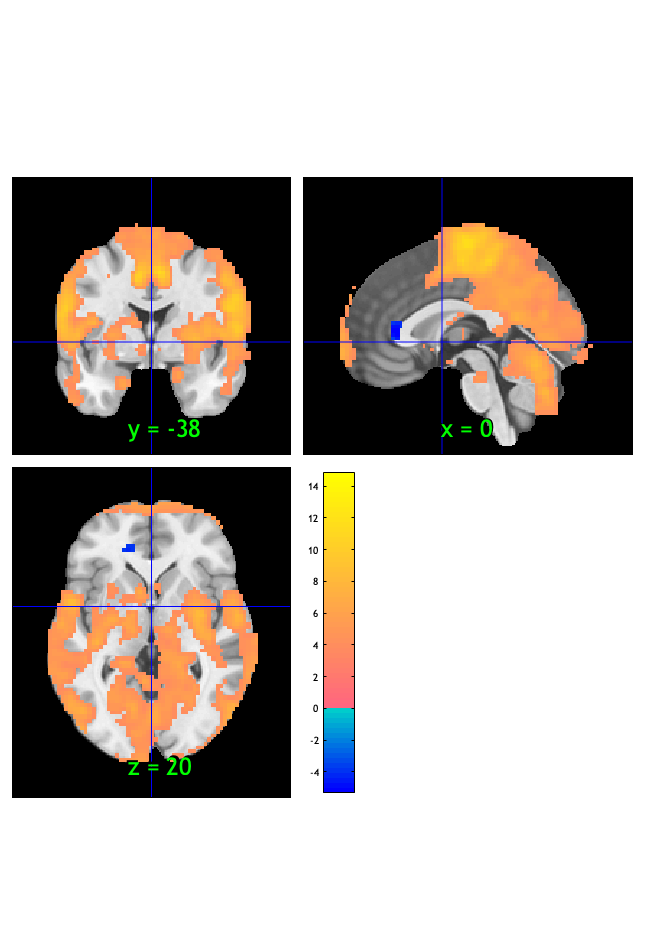

orthviews(fdr_t);

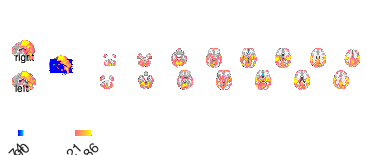

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1003 voxels displayed, 40975 not displayed on these slices
sagittal montage: 1063 voxels displayed, 40915 not displayed on these slices
sagittal montage: 928 voxels displayed, 41050 not displayed on these slices
axial montage: 7275 voxels displayed, 34703 not displayed on these slices
axial montage: 7833 voxels displayed, 34145 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;
write(fdr_t, 'fname', strcat('/Users/h/Desktop/', contrast_of_interest, '_fdr_t.nii'), 'overwrite');

Writing: 
/Users/h/Desktop/P_VC_STIM_stimlin_high_gt_low_fdr_t.nii


#### Pain > VC :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low     words_low      testr_high       words_high    
    _________    ____________    __________    _________________

    -0.19405     {'work'    }     0.25868      {'movements'    }
    -0.19065     {'working' }     0.24072      {'sensorimotor' }
    -0.17032     {'memory'  }     0.23963      {'motor'        }
    -0.16458     {'correct' }     0.23779      {'hand'         }
    -0.15665     {'conflict'}     0.23014      {'somatosensory'}
    -0.14766     {'response'}     0.21895      {'sensory'      }
    -0.14599     {'demand'  }      0.2121      {'finger'       }
    -0.14414     {'letter'  }     0.20928      {'muscle'       }
     -0.1412     {'decision'}     0.20359      {'rest'         }
    -0.13898     {'pair'    }     0.20067    

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Pain > VC :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.0068	1.1599	0.2495	0.0000	
Cog Wholebrain	0.0182	4.6339	0.0000	1.0000	***
Emo Wholebrain	-0.0227	-4.0199	0.0001	1.0000	***
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    0.0067819     0.0058723     1.1549       0.25157    0.12832 
    {'Cog Wholebrain' }      0.01816     0.0039193     4.6337    1.3751e-05    0.51485 
    {'Emo Wholebrain' }    -0.022684     0.0056399    -4.0221    0.00012992    -0.4469 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [19.0007 20.0007 21.0007]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    0.0092118     0.0057592     1.5995       0.11366    0.17772 
    {'Cog Wholebrain' }     0.016894     0.0035321     4.7831    7.7487e-06    0.53146 
    {'Emo Wholebrain' }    -0.024391     0.0055455    -4.3983    3.3296e-05    -0.4887 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [22.0007 23.0007 24.0007]


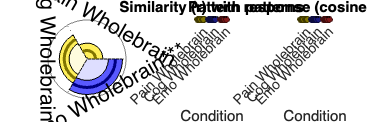

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Vicarious > (Pain & Cognitive) 

# Linear effect of stimulus intensity (low < med < high)

% clear all;
% close all;

#### Vicarious > PC :: load dataset

clear all;
close all;

contrast_of_interest = 'V_PC_STIM_stimlin_high_gt_low'

contrast_of_interest = 'V_PC_STIM_stimlin_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_STIM_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32347188 bytes
Loading image number:    81
Elapsed time is 3.960511 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7715301  Bit rate: 22.88 bits


#### Vicarious > PC :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:09:57 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Vicarious > PC :: Plot diagnostics, before l2norm

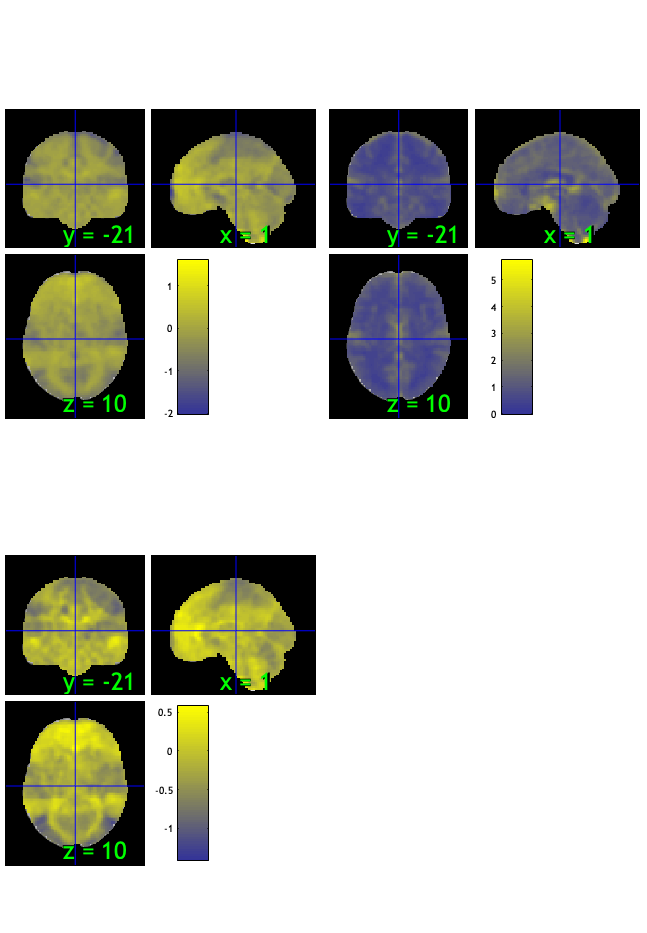

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 28.40%
Expected 4.05 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 51 55 
Uncorrected: 6 images		Cases 20 36 51 52 55 73 

Retained 11 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 51.85%
Expected 4.05 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               

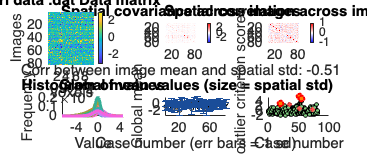

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:10:29 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious > PC :: run robfit

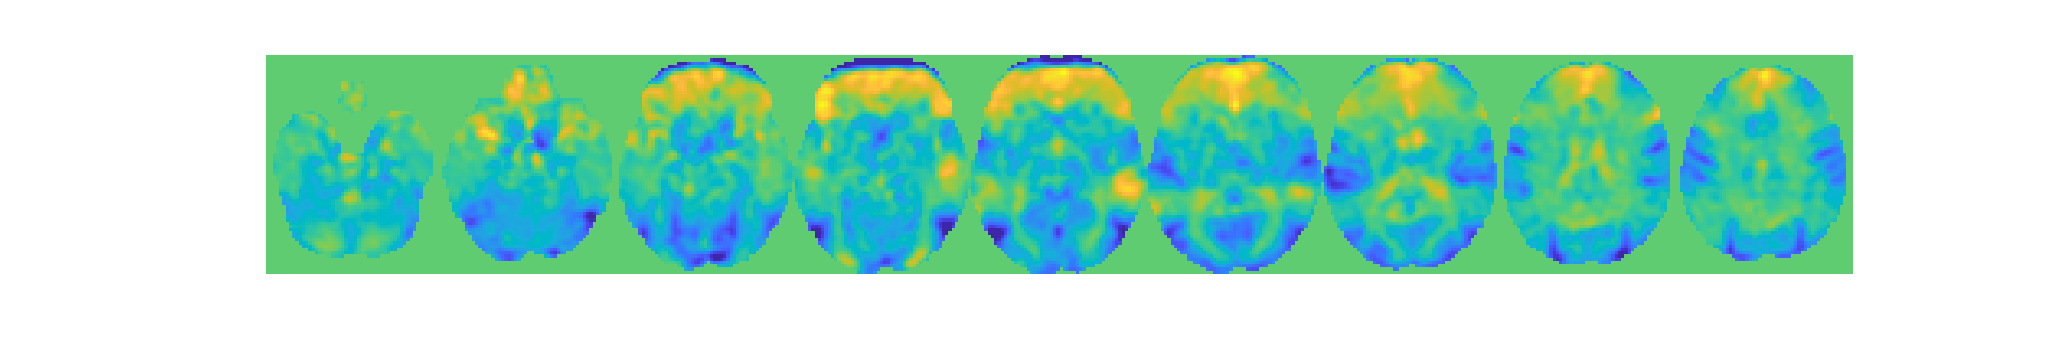

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious > PC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 81


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 3 participants, size is now 78


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0051"    "participants that are outliers:... sub-0093"    "participants that are outliers:... sub-0098"



disp(n);

    {'sub-0051'}    {'sub-0093'}    {'sub-0098'}



#### Vicarious > PC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious > PC :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


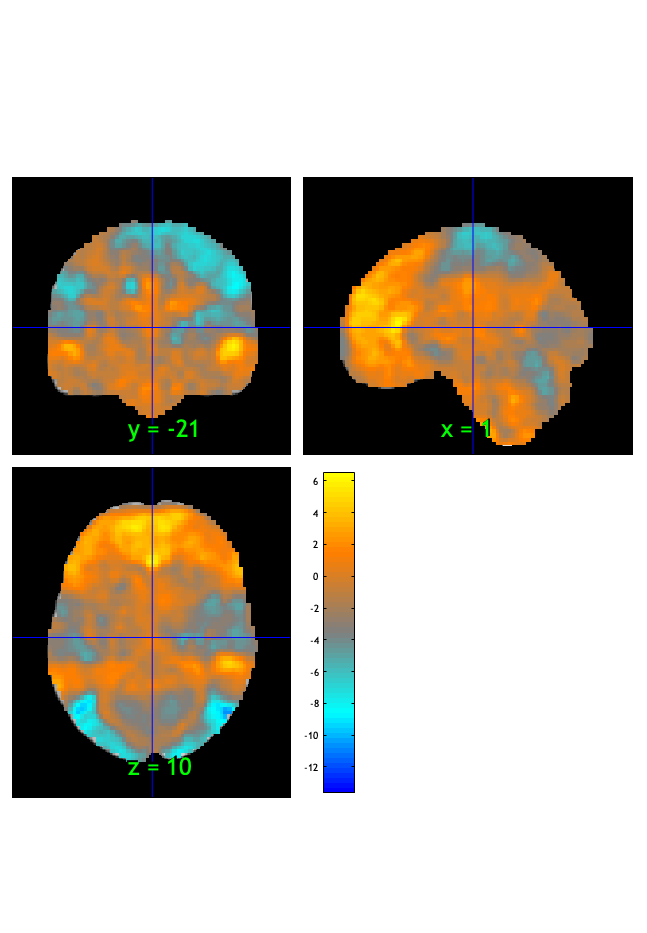

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:10:33 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.020212

Image   1
 64 contig. clusters, sizes   1 to 33934
Positive effect: 5899 voxels, min p-value: 0.00000000
Negative effect: 34460 voxels, min p-value: 0.00000000


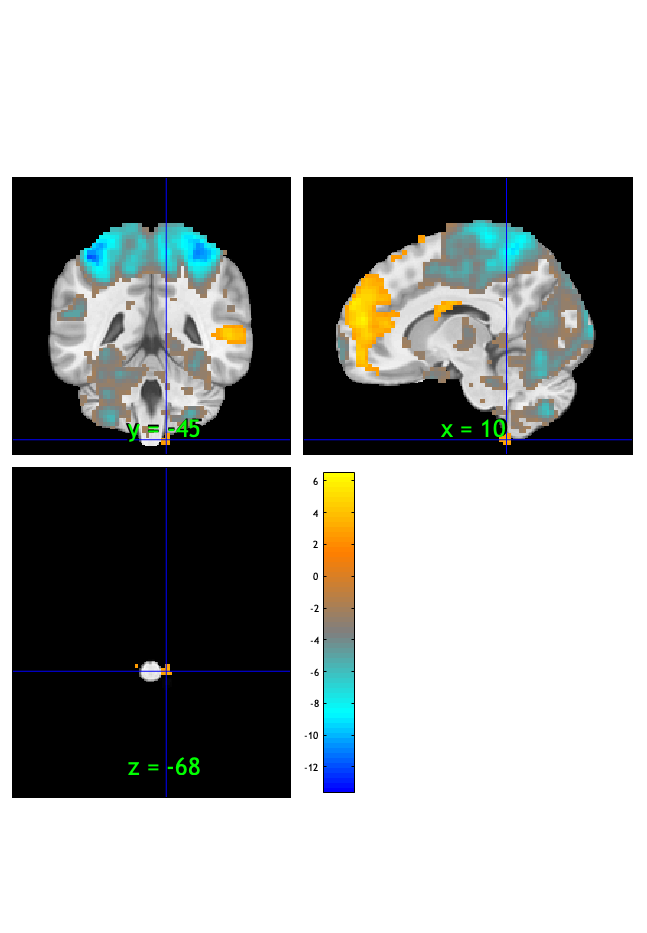

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:10:35 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


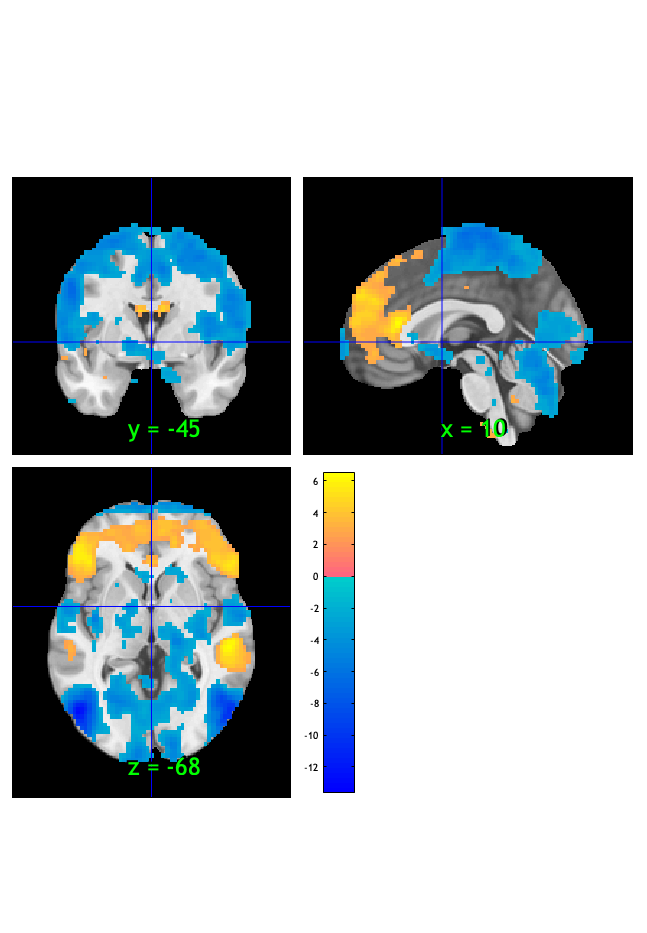

orthviews(fdr_t);

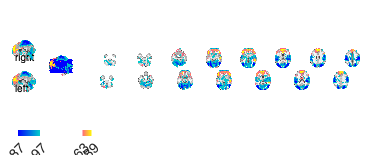

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 897 voxels displayed, 39462 not displayed on these slices
sagittal montage: 954 voxels displayed, 39405 not displayed on these slices
sagittal montage: 809 voxels displayed, 39550 not displayed on these slices
axial montage: 6878 voxels displayed, 33481 not displayed on these slices
axial montage: 7440 voxels displayed, 32919 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;
write(fdr_t, 'fname', strcat('/Users/h/Desktop/', contrast_of_interest, '_fdr_t.nii'), 'overwrite')

Writing: 
/Users/h/Desktop/V_PC_STIM_stimlin_high_gt_low_fdr_t.nii


#### Vicarious > PC :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low        testr_high      words_high  
    _________    ________________    __________    ______________

    -0.37644     {'movements'   }     0.27726      {'affect'    }
     -0.3734     {'visual'      }     0.26078      {'social'    }
    -0.36758     {'hand'        }     0.25628      {'emotion'   }
     -0.3343     {'spatial'     }     0.25541      {'person'    }
    -0.31258     {'eye'         }     0.25535      {'negative'  }
    -0.30586     {'motion'      }     0.25126      {'trait'     }
    -0.29569     {'finger'      }     0.24924      {'regulation'}
    -0.29262     {'position'    }     0.24363      {'affective' }
    -0.29088     {'motor'       }     0.23761      {'valence'   }
    -0.28315     {'sensorimotor'} 

Vicarious > PC **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0058	-1.0111	0.3150	0.0000	
Cog Wholebrain	-0.0002	-0.0512	0.9593	0.0000	
Emo Wholebrain	0.0057	0.8980	0.3719	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value     Std_Error        T           P       Cohens_d 
    ___________________    ___________    _________    _________    _______    _________

    {'Pain Wholebrain'}     -0.0058285    0.0057736      -1.0095    0.31577     -0.11217
    {'Cog Wholebrain' }    -0.00020746    0.0041046    -0.050544    0.95982    -0.005616
    {'Emo Wholebrain' }      0.0057023    0.0063494      0.89809    0.37183     0.099788



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [19.0009 20.0009 21.0009]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value     Std_Error       T           P       Cohens_d 
    ___________________    ___________    _________    ________    _______    _________

    {'Pain Wholebrain'}     -0.0065979     0.005749     -1.1476    0.25454     -0.12752
    {'Cog Wholebrain' }    -0.00088385    0.0037433    -0.23612    0.81395    -0.026235
    {'Emo Wholebrain' }      0.0071357    0.0062896      1.1345    0.25996      0.12606



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [22.0009 23.0009 24.0009]


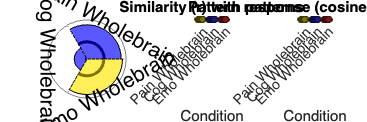

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Cognitive > (Pain & Vicarious) 

# Linear effect of stimulus intensity (low < med < high)

#### Cognitive > PV :: load dataset

clear all;
close all;

contrast_of_interest = 'C_PV_STIM_stimlin_high_gt_low'

contrast_of_interest = 'C_PV_STIM_stimlin_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_STIM_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy

};
index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32347188 bytes
Loading image number:    81
Elapsed time is 4.495560 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7705454  Bit rate: 22.88 bits


#### Cognitive > PV :: `check data coverage`

m = mean(con_data_obj);
% m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:11:30 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


#### Cognitive > PV :: Plot diagnostics, before l2norm

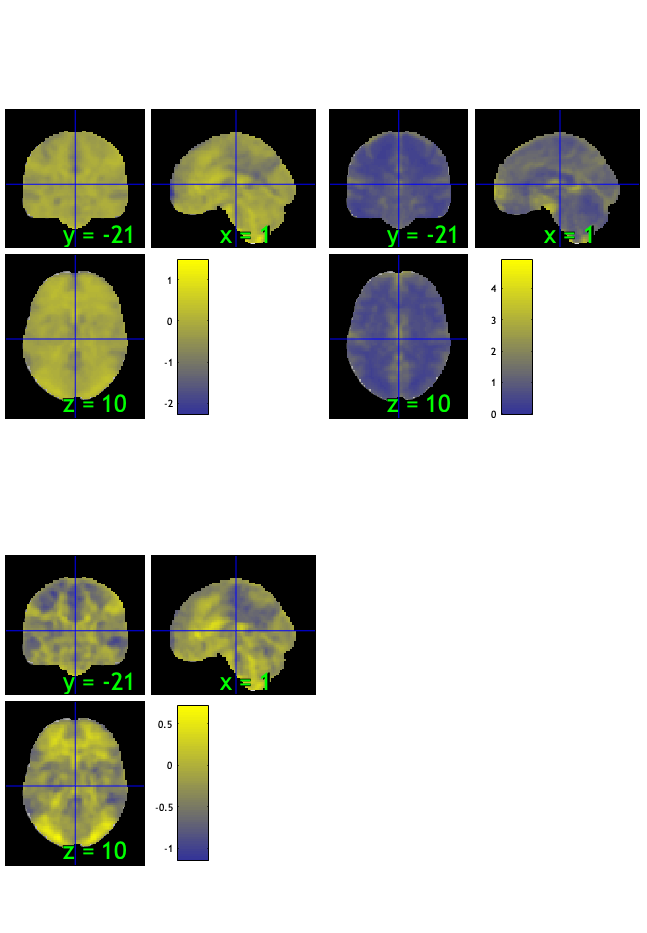

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 37.04%
Expected 4.05 outside 95% ellipsoid, found   8

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 51 
Uncorrected: 8 images		Cases 20 44 51 52 55 62 71 81 

Retained 11 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 58.02%
Expected 4.05 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                               

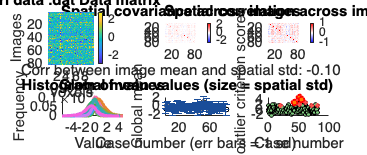

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:12:03 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive > PV :: run robfit

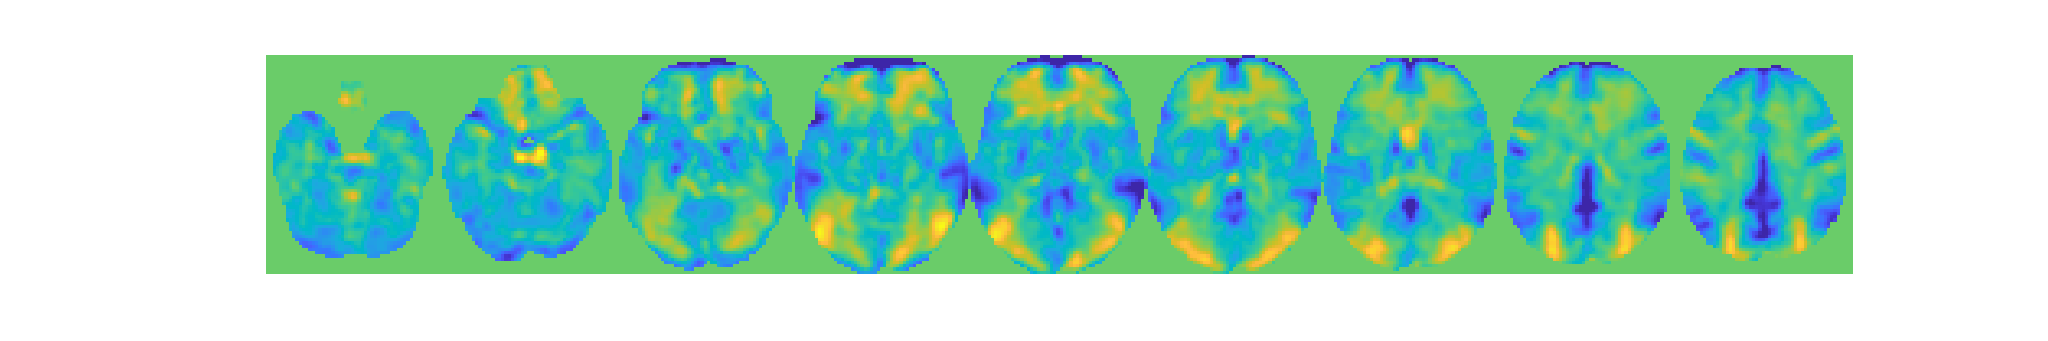

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive > PV :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 81


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 3 participants, size is now 78


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0082"    "participants that are outliers:... sub-0093"    "participants that are outliers:... sub-0098"



disp(n);

    {'sub-0082'}    {'sub-0093'}    {'sub-0098'}



#### Cognitive > PV:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive > PV :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


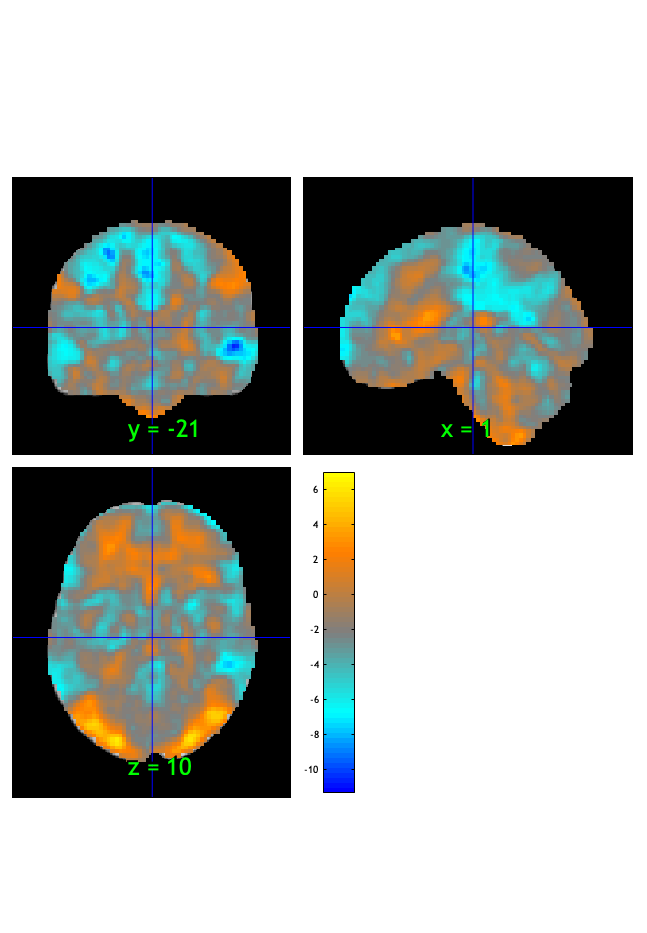

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:12:07 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.024744

Image   1
 40 contig. clusters, sizes   1 to 47366
Positive effect: 3492 voxels, min p-value: 0.00000000
Negative effect: 45919 voxels, min p-value: 0.00000000


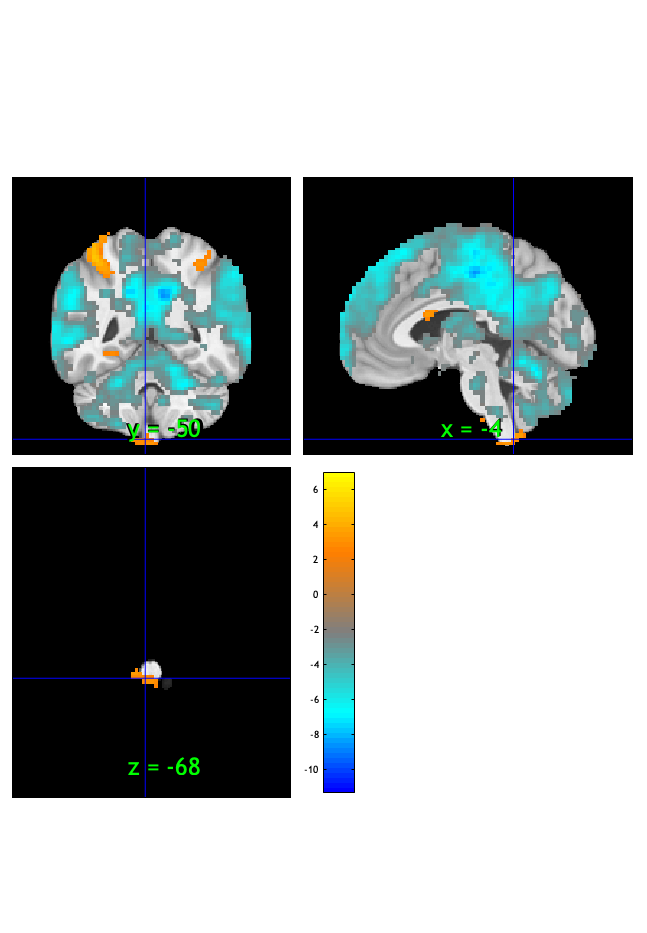

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:12:10 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


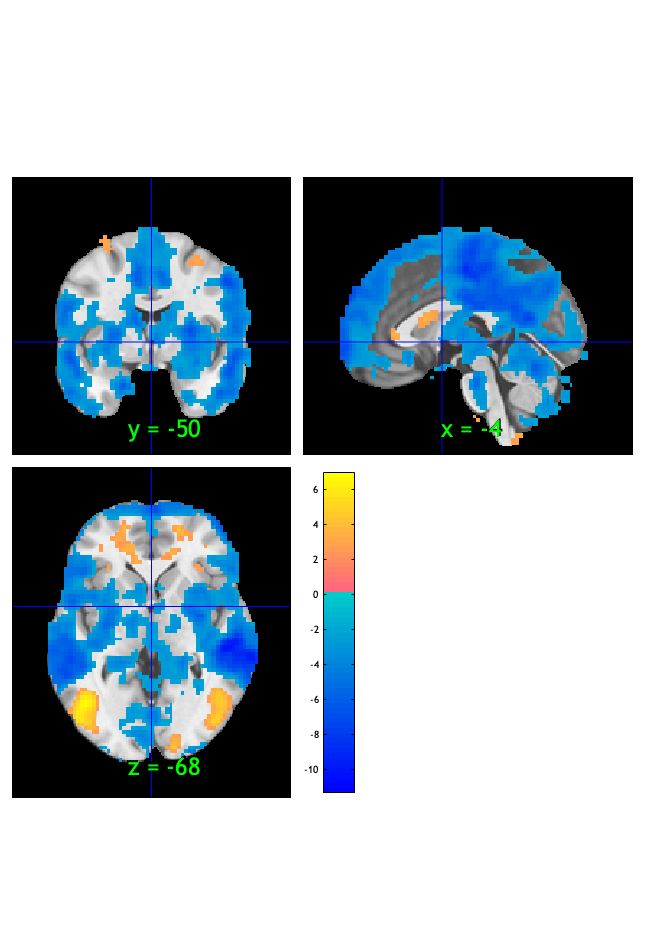

orthviews(fdr_t);

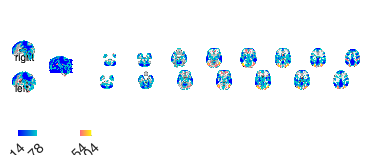

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1351 voxels displayed, 48060 not displayed on these slices
sagittal montage: 1259 voxels displayed, 48152 not displayed on these slices
sagittal montage: 1311 voxels displayed, 48100 not displayed on these slices
axial montage: 9276 voxels displayed, 40135 not displayed on these slices
axial montage: 9850 voxels displayed, 39561 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;
write(fdr_t, 'fname', strcat('/Users/h/Desktop/', contrast_of_interest, '_fdr_t.nii'), 'overwrite')

Writing: 
/Users/h/Desktop/C_PV_STIM_stimlin_high_gt_low_fdr_t.nii


#### Cognitive > PV :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low         words_low          testr_high      words_high   
    _________    ____________________    __________    _______________

    -0.21045     {'stories'         }     0.33271      {'visual'     }
    -0.20917     {'default'         }     0.27846      {'shape'      }
    -0.20415     {'story'           }     0.25803      {'object'     }
     -0.1988     {'person'          }     0.25585      {'eye'        }
    -0.18855     {'selfreferential' }     0.24842      {'objects'    }
    -0.18699     {'restingstate'    }     0.24816      {'attention'  }
    -0.18593     {'rating'          }     0.22062      {'spatial'    }
    -0.18321     {'autobiographical'}     0.20792      {'rotation'   }
     -0.1776     {'self'            }     0.20505 

Cognitive > PV **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.0005	0.0926	0.9265	0.0000	
Cog Wholebrain	-0.0204	-4.8539	0.0000	1.0000	***
Emo Wholebrain	0.0178	3.0748	0.0029	1.0000	**
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T            P         Cohens_d
    ___________________    __________    _________    ________    __________    ________

    {'Pain Wholebrain'}    0.00053947    0.0056199    0.095993       0.92377    0.010666
    {'Cog Wholebrain' }      -0.02043    0.0042075     -4.8557    5.8469e-06    -0.53952
    {'Emo Wholebrain' }      0.017787    0.0057867      3.0738     0.0028897     0.34154



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [19.0010 20.0010 21.0010]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T            P         Cohens_d 
    ___________________    __________    _________    ________    __________    _________

    {'Pain Wholebrain'}    -0.0011099    0.0055131    -0.20132       0.84096    -0.022369
    {'Cog Wholebrain' }     -0.019794     0.004027     -4.9154    4.6301e-06     -0.54616
    {'Emo Wholebrain' }        0.0193    0.0056061      3.4426     0.0009191      0.38251



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [22.0010 23.0010 24.0010]


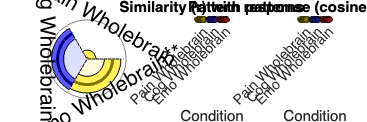

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;


# Manipulation check Rating

# motor contrast

#### motor only :: load dataset

clear all;
close all;

contrast_of_interest = 'motor'

contrast_of_interest = 'motor'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_STIM_cue_high_gt_low','V_PC_CUE_STIM_cue_high_gt_low','C_PV_CUE_STIM_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_STIM_cue_high_gt_low','V_simple_CUE_STIM_cue_high_gt_low','C_simple_CUE_STIM_cue_high_gt_low',...% cue epoch dummy

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32347188 bytes
Loading image number:    81
Elapsed time is 3.145138 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7719962  Bit rate: 22.88 bits


#### motor only :: `check data coverage`

m = mean(con_data_obj);
% m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:13:03 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


#### motor only :: Plot diagnostics, before l2norm

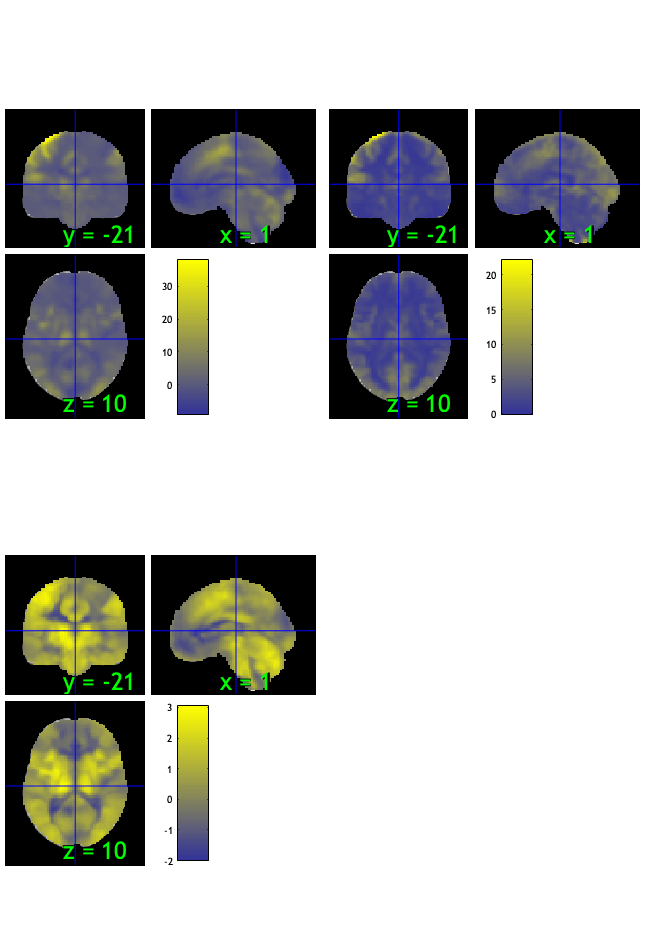

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 37.04%
Expected 4.05 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 41 
Uncorrected: 5 images		Cases 3 11 22 41 47 

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.68%
Expected 4.05 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 17 
Uncorrected: 5 images		Cases 17 40 51 66 75 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               

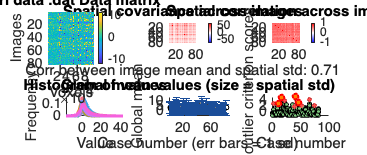

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:13:35 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### motor only :: run robfit

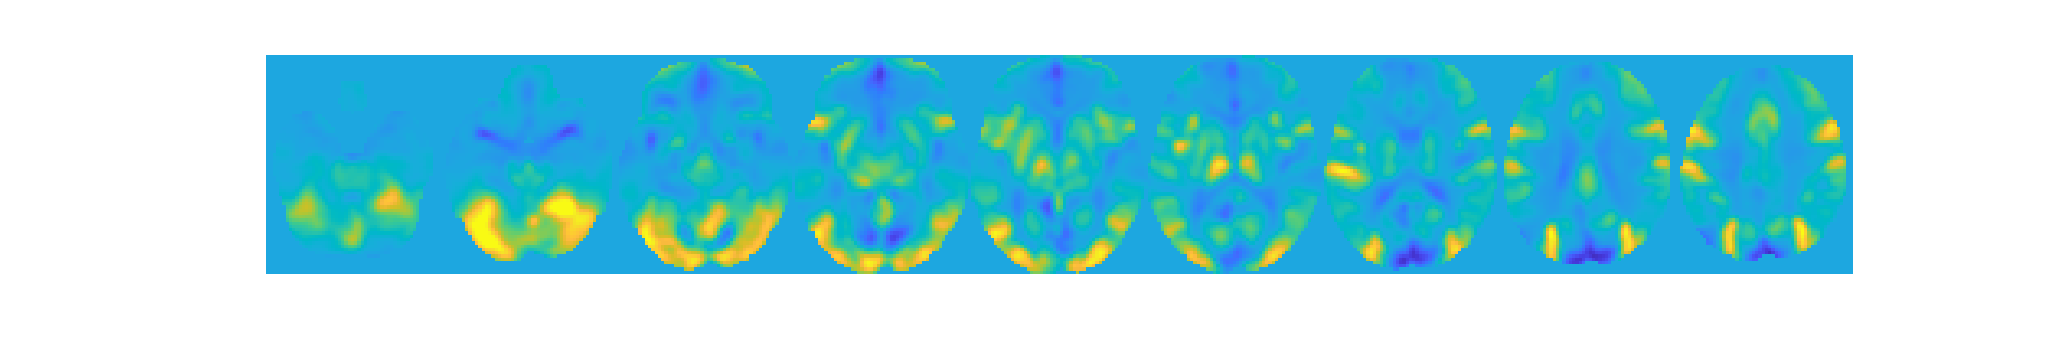

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### motor only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 81


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 4 participants, size is now 77


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0036"    "participants that are outliers:... sub-0044"    "participants that are outliers:... sub-0080"    "participants that are outliers:... sub-0088"



disp(n);

    {'sub-0036'}    {'sub-0044'}    {'sub-0080'}    {'sub-0088'}



#### motor only:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### motor only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


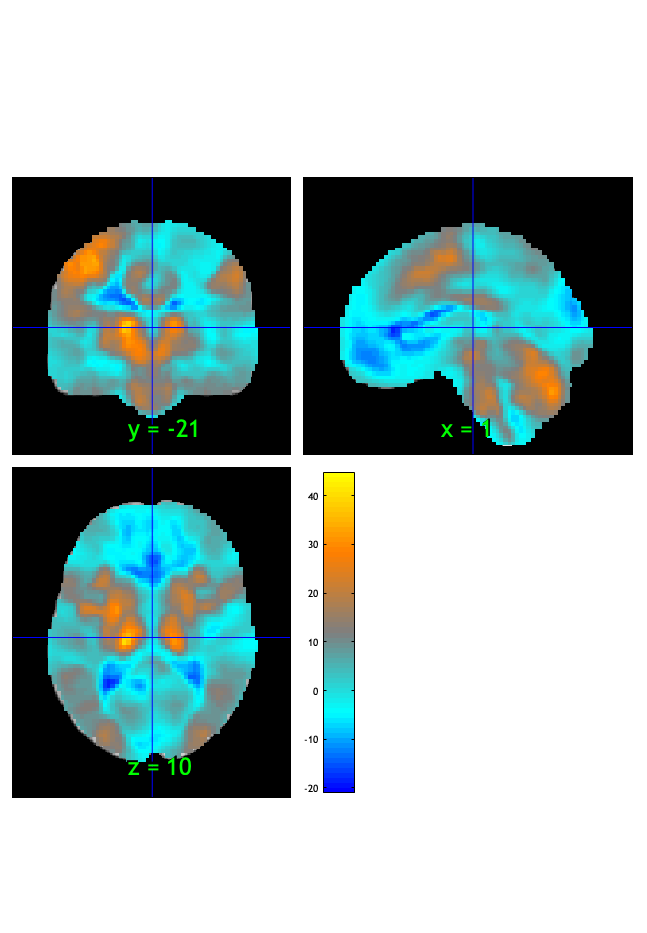

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:13:40 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.041486

Image   1
 10 contig. clusters, sizes   1 to 82754
Positive effect: 66753 voxels, min p-value: 0.00000000
Negative effect: 16083 voxels, min p-value: 0.00000000


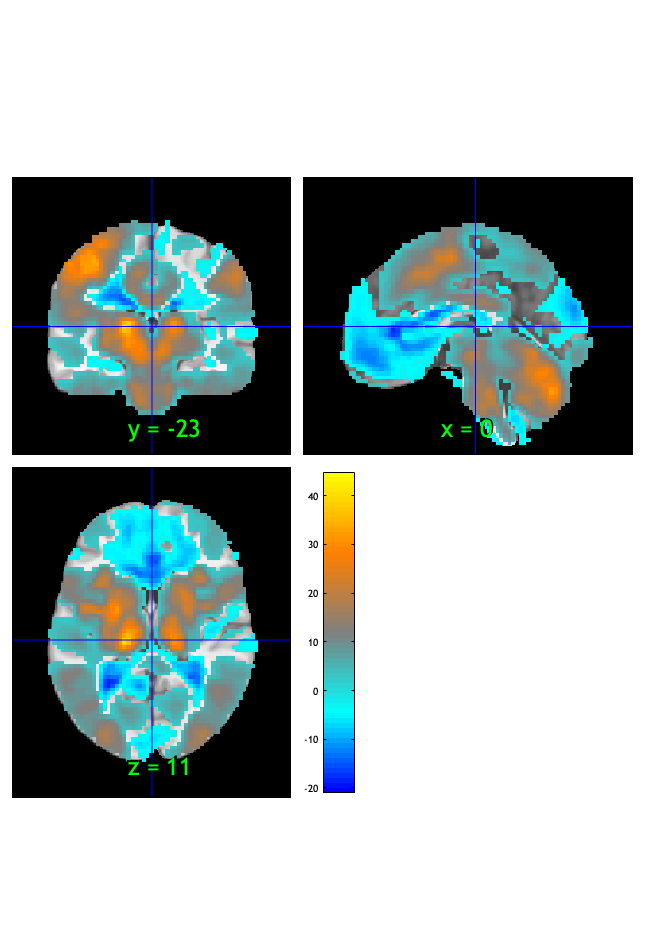

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              18:13:41 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


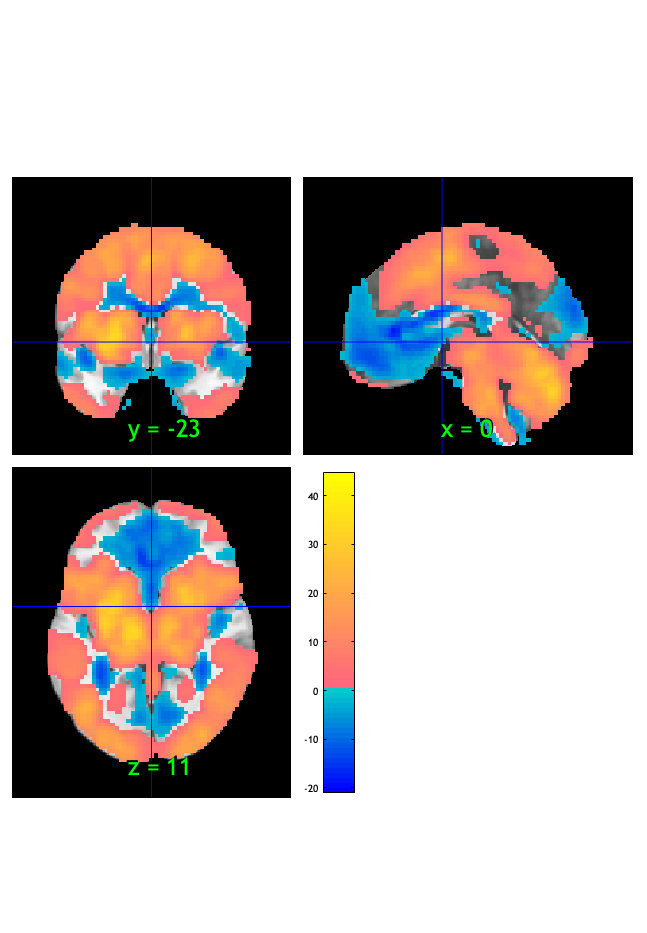

orthviews(fdr_t);

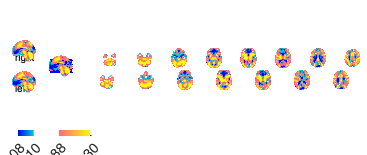

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 2077 voxels displayed, 80759 not displayed on these slices
sagittal montage: 2071 voxels displayed, 80765 not displayed on these slices
sagittal montage: 1957 voxels displayed, 80879 not displayed on these slices
axial montage: 15350 voxels displayed, 67486 not displayed on these slices
axial montage: 16686 voxels displayed, 66150 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;



#### motor only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high   
    _________    ______________    __________    ________________

    -0.33403     {'trait'     }     0.38523      {'movements'   }
    -0.32385     {'positive'  }     0.35892      {'execution'   }
    -0.32292     {'negative'  }     0.35482      {'hand'        }
    -0.30972     {'age'       }     0.32915      {'motor'       }
    -0.29693     {'personal'  }     0.32391      {'visual'      }
    -0.29204     {'depression'}      0.3129      {'finger'      }
    -0.28797     {'emotion'   }     0.28624      {'sensorimotor'}
    -0.28769     {'disorder'  }     0.28597      {'action'      }
    -0.28606     {'affect'    }     0.28405      {'hands'       }
    -0.28267     {'person'    }   

motor only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0190	-4.5393	0.0000	1.0000	***
Cog Wholebrain	0.0315	13.0554	0.0000	1.0000	***
Emo Wholebrain	-0.0102	-2.5237	0.0136	1.0000	*
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.019015     0.0041886    -4.5397    1.9632e-05    -0.50441
    {'Cog Wholebrain' }     0.031529     0.0024132     13.065    2.2204e-15      1.4517
    {'Emo Wholebrain' }    -0.010242     0.0040571    -2.5244      0.013569    -0.28049



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [19.0011 20.0011 21.0011]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.014386     0.0038038     -3.782    0.00029872    -0.42022
    {'Cog Wholebrain' }     0.028578     0.0022056     12.957    2.2204e-15      1.4396
    {'Emo Wholebrain' }    -0.012545     0.0037215    -3.3711     0.0011552    -0.37456



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [22.0011 23.0011 24.0011]


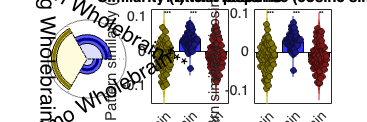

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;

% save html
% pubdir = pwd;
% pubfilename = '6cond_cueeffect_contrast.mlx';
% 
% p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
%   'format', 'html', 'outputDir', pubdir, ...
%   'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
% htmlfile = publish(pubfilename, p);